# Sliding Mode Control Design -- Super-Twisting (Minimal Chattering)

The seesaw is open-loop unstable and the plant carries unmodelled matched perturbations (Coulomb friction, encoder quantization, mass offset, linearisation error). A first-order (relay) sliding mode would reject all of this but at the cost of a switching control voltage that the VoltPAQ/motor cannot follow cleanly -- chattering.

This script designs a second-order sliding mode using the super-twisting algorithm (STA). The STA acts on the sliding variable s while keeping the commanded voltage CONTINUOUS (no sign() in the output path), so the actuator sees a smooth signal -- chattering is minimised -- yet finite- time convergence and matched-disturbance rejection are retained.

State vector: x = [x_c; x_c_dot; alpha; alpha_dot] Requires: seesaw_params.m (plant), tuned_params.mat (B_eq) Outputs: controller_smc.mat, figures

Control law: s = S * x (sliding variable) u_eq = -(S*B)\(S*A) * x (equivalent control) u_st = (1/(S*B)) * ( -k1*sqrt(`s`)*sign(s) + v ) v_dot = -k2 * sign(s) (STA integrator state) u = sat( u_eq + u_st , +/-V_sat )

clear; close all; clc

set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');
set(groot, 'defaultTextInterpreter', 'latex');

root   = fileparts(fileparts(fileparts(mfilename('fullpath'))));
figdir = fullfile(root, 'docs', 'figures');

## 1. Build plant for current configuration

run(fullfile('scripts', 'config', 'seesaw_params.m'))

  J_pivot = 0.4071 kg*m^2 (J_cg + M*Dc^2 = 0.395 + 0.0121)
  B_eq = 5.00 N*s/m (cart friction, tunable -- Good ref Eq. 2.1)
  alpha_f = 1.5532 (motor force constant)
  B_emf = 6.97 N*s/m (inside F_c, not added separately)
  B_total = 11.97 N*s/m (B_eq + B_emf)
  [Phase 1] A_cart, B_cart, C_cart, D_cart computed.
  [Phase 2] A_sw, B_sw, C_sw, D_sw computed (linearised seesaw).
  Seesaw SS eigenvalues (corrected linearisation):
    lambda_1 = 2.6283
    lambda_2 = -0.4849
    lambda_3 = -2.2101
    lambda_4 = -31.8910
  RHP pole: 2.6283 rad/s (expected ~+2.24 rad/s -- confirms correct linearisation).

All parameters loaded successfully.
Amplifier gain K_a = 1 (VERIFY switch on VoltPAQ!)
Voltage saturation = +/- 6.0 V
Max angle = +/- 11.5 deg (= physical stops)
Motor model: L_m = 0 (reduced, matches Good ref Eq. 2.3)
  Cart mass m_c = 0.380 kg (no reflected rotor inertia -- matches Good ref)
SS matrices ready: A_cart/B_c

tuned = load(fullfile( 'data', 'tuned_params.mat'));
A = tuned.A_sw;             % hardware-tuned 4x4 (B_eq fitted to data)
B = tuned.B_sw;             % hardware-tuned 4x1

n = size(A, 1);
poles_ol   = eig(A);
p_unstable = max(real(poles_ol));

fprintf('Open-loop poles: '); fprintf('%+.3f  ', poles_ol); fprintf('\n')

Open-loop poles: -36.496  +2.611  -2.251  -0.419  


fprintf('Unstable mode:   p_OL = %+.3f rad/s (seesaw fall rate)\n', p_unstable)

Unstable mode:   p_OL = +2.611 rad/s (seesaw fall rate)


fprintf('Controllability rank: %d/%d\n\n', rank(ctrb(A, B)), n)

Controllability rank: 4/4



if rank(ctrb(A, B)) < n
    error('Plant not controllable -- SMC surface cannot be placed.')
end

## 2. Sliding surface via regular form + pole placement

Orthonormal T maps the input to the last channel: T*B = [0;0;0;bbar]. In z = T*x the dynamics split into a 3-state "sliding" subsystem driven by the scalar z2, which is treated as a virtual control:

Choosing z2 = -F*z1 places the 3 poles of (A11 - A12*F): these are the poles the system shows WHILE sliding. The surface is sigma = F*z1 + z2, hence S = [F 1]*T in original coordinates.

N  = null(B');                      % 4x3, orthonormal, spans null(B')
Tr = [N'; (B/norm(B))'];            % orthonormal regular-form transform
Abar = Tr * A * Tr';
Bbar = Tr * B;                      % = [0;0;0;norm(B)]

A11 = Abar(1:n-1, 1:n-1);
A12 = Abar(1:n-1, n);

% Sliding-mode poles (order n-1 = 3). Must outrun the open-loop divergence.
% Dominant complex pair governs the alpha-balancing motion; the real pole
% damps the cart. Kept in the same bandwidth window as the PP/LQR designs
% so the required voltage stays within saturation.
sigma_s = 4.0;                      % dominant decay rate [rad/s]
zeta_s  = 0.80;                     % dominant pair damping
wn_s    = sigma_s / zeta_s;
p_real  = -1.6 * sigma_s;           % cart-mode real pole
p_slide = [ -sigma_s + 1j*wn_s*sqrt(1-zeta_s^2);
    -sigma_s - 1j*wn_s*sqrt(1-zeta_s^2);
    p_real ];

F = place(A11, A12, p_slide);
S = [F, 1] * Tr;                    % sliding surface row vector, s = S*x

SB = S * B;
if abs(SB) < 1e-9
    error('S*B is singular -- sliding surface is not well posed.')
end

% Equivalent control gain: u_eq = -K_eq * x
K_eq = (SB) \ (S * A);

% Verify the achieved sliding dynamics
A_slide = A11 - A12 * F;
fprintf('Sliding-surface poles (achieved): '); fprintf('%+.3f%+.3fj  ', ...
    [real(eig(A_slide)) imag(eig(A_slide))]'); fprintf('\n')

Sliding-surface poles (achieved): -6.400+0.000j  -4.000+3.000j  -4.000-3.000j  

fprintf('S   = [%+.4f %+.4f %+.4f %+.4f]\n', S)

S   = [+17.9384 +2.1508 -29.9442 -9.9494]


fprintf('S*B = %+.4f\n\n', SB)

S*B = +2.8803



## 3. Super-twisting reaching-law gains

On the surface the perturbed reaching dynamics are s_dot = -k1*sqrt(`s`)*sign(s) + v + d(t) v_dot = -k2*sign(s) Finite-time convergence holds for k1 = 1.5*sqrt(L), k2 = 1.1*L, where L bounds the rate of the matched perturbation expressed in s-coordinates. L is the single robustness knob -- raise it for stronger rejection, lower it for an even smoother voltage.

L_dist = 18;                        % matched-perturbation rate bound [1/s^2]
k1 = 1.5 * sqrt(L_dist);
k2 = 1.1 * L_dist;
fprintf('Super-twisting gains: L = %.1f -> k1 = %.3f, k2 = %.3f\n\n', ...
    L_dist, k1, k2)

Super-twisting gains: L = 18.0 -> k1 = 6.364, k2 = 19.800



## 4. Closed-loop simulation -- STA vs. classic relay SMC

Both controllers use the SAME surface and equivalent control; only the reaching law differs. A matched disturbance (offset mass + Coulomb friction) and encoder quantization are injected so the chattering comparison is meaningful.

Ts       = 0.002;                   % QUARC fixed step [s]
t        = (0:Ts:6)';
x0       = [0; 0; deg2rad(2.5); 0]; % initial seesaw tilt
q_alpha  = K_E_SW / K_gs;           % seesaw encoder resolution [rad]
q_xc     = K_ec;                    % cart encoder resolution [m]

% Matched disturbance d(t) entering through the input channel [N-equiv].
% Constant bias-load torque + a slow drift to exercise the STA integrator.
d_fun = @(tt) 0.6 + 0.4 * sin(0.8 * tt);

phi_bl = 0.05;                      % boundary-layer width for the relay law

sta = sim_smc(A, B, S, K_eq, t, x0, V_sat, q_xc, q_alpha, d_fun, ...
    'sta', k1, k2, []);
rel = sim_smc(A, B, S, K_eq, t, x0, V_sat, q_xc, q_alpha, d_fun, ...
    'relay', k1, k2, phi_bl);

% Chattering metric: total variation of the control signal per second.
tv_sta = sum(abs(diff(sta.u))) / (t(end) - t(1));
tv_rel = sum(abs(diff(rel.u))) / (t(end) - t(1));
fprintf('Control total variation [V/s]:  STA = %.2f   relay(boundary) = %.2f\n', ...
    tv_sta, tv_rel)

Control total variation [V/s]:  STA = 16.01   relay(boundary) = 122.37


fprintf('Chattering reduction: %.1fx smoother voltage with STA\n\n', ...
    tv_rel / max(tv_sta, eps))

Chattering reduction: 7.6x smoother voltage with STA




fprintf('Settling (|alpha| < 0.2 deg):    STA = %.2f s\n', ...
    settle_time(t, sta.x(:,3), deg2rad(0.2)))

Settling (|alpha| < 0.2 deg):    STA = 0.82 s


fprintf('Peak voltage:                    STA = %.2f V (limit %.2f V)\n', ...
    max(abs(sta.u)), V_sat)

Peak voltage:                    STA = 6.00 V (limit 6.00 V)


## 5. Figures

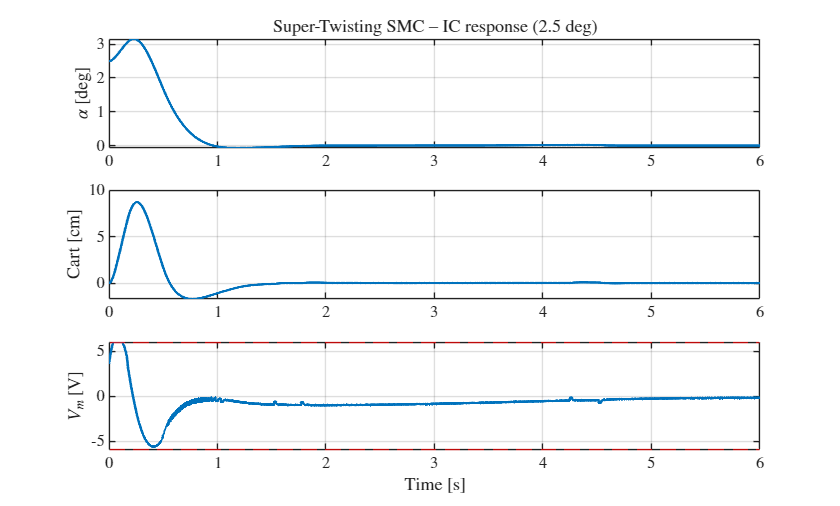

figure('Name', 'SMC -- super-twisting response')
subplot(3,1,1)
plot(t, sta.x(:,3)*180/pi, 'LineWidth', 1.3); grid on
ylabel('$\alpha$ [deg]')
title(sprintf('Super-Twisting SMC -- IC response (%.1f deg)', ...
    x0(3)*180/pi))
subplot(3,1,2)
plot(t, sta.x(:,1)*100, 'LineWidth', 1.3); grid on
ylabel('Cart [cm]')
subplot(3,1,3)
plot(t, sta.u, 'LineWidth', 1.3); grid on
yline( V_sat, 'r--'); yline(-V_sat, 'r--')
ylabel('$V_m$ [V]'); xlabel('Time [s]')

saveas(gcf, fullfile(figdir, 'SMC-STA-Response.png'))

Error using saveas (line 138)
Invalid or missing path: C:\docs\figures\SMC-STA-Response.png


figure('Name', 'SMC -- chattering comparison')
subplot(2,1,1); hold on; grid on
plot(t, rel.u, 'LineWidth', 1.0)
plot(t, sta.u, 'LineWidth', 1.3)
ylabel('$V_m$ [V]')
legend('Relay SMC (boundary layer)', 'Super-twisting SMC', ...
    'Location', 'best')
title('Commanded Voltage -- Chattering Comparison')
subplot(2,1,2); hold on; grid on
plot(t, rel.s, 'LineWidth', 1.0)
plot(t, sta.s, 'LineWidth', 1.3)
ylabel('Sliding variable $s$'); xlabel('Time [s]')
legend('Relay SMC', 'Super-twisting SMC', 'Location', 'best')
saveas(gcf, fullfile(figdir, 'SMC-Chattering-Comparison.png'))

figure('Name', 'SMC -- phase portrait')
plot(sta.s, sta.s_dot, 'LineWidth', 1.3); grid on
xlabel('$s$'); ylabel('$\dot{s}$')
title('Super-Twisting Reaching Trajectory ($s,\dot{s}$)')
saveas(gcf, fullfile(figdir, 'SMC-Phase-Portrait.png'))

## 6. Save controller

save(fullfile(root, 'data', 'controller_smc.mat'), ...
    'S', 'K_eq', 'k1', 'k2', 'L_dist', 'p_slide', 'sigma_s', 'zeta_s', ...
    'p_real', 'V_sat', 'Ts', 'phi_bl')
fprintf('Saved data/controller_smc.mat\n')
fprintf(['Deploy: s = S*x;  v is an integrator state (v_dot = -k2*sign(s));\n' ...
    '        u = sat( -K_eq*x + (-k1*sqrt(|s|)*sign(s) + v)/(S*B), V_sat )\n'])

## Helpers --------------------------------------------------------------

function out = sim_smc(A, B, S, K_eq, t, x0, Vsat, q_xc, q_al, d_fun, ...
    law, k1, k2, phi)
% Fixed-step simulation of the plant under SMC. The plant is integrated
% with RK4; the controller runs at the sample rate with quantized
% measurements, mirroring the QUARC deployment.
N  = numel(t);
h  = t(2) - t(1);
SB = S * B;
x  = x0(:);
v  = 0;                                  % STA integrator state
X  = zeros(N, 4); U = zeros(N,1); Sg = zeros(N,1); Sd = zeros(N,1);

f = @(xx, uu, dd) A*xx + B*(uu + dd);    % matched disturbance dd

for k = 1:N
    % --- quantized measurement -> sliding variable ---
    xm = x;
    xm(1) = round(x(1)/q_xc) * q_xc;
    xm(3) = round(x(3)/q_al) * q_al;
    s  = S * xm;

    % --- reaching law ---
    switch law
        case 'sta'
            u_n = (-k1*sqrt(abs(s))*sign(s) + v) / SB;
            v   = v - k2*sign(s)*h;          % integrator update
        case 'relay'
            % classic first-order law, boundary-layer smoothed
            u_n = (-(k1+k2)*sat_fun(s/phi)) / SB;
    end
    u = -K_eq*xm + u_n;
    u = max(min(u, Vsat), -Vsat);

    % --- log ---
    d = d_fun(t(k));
    X(k,:) = x';  U(k) = u;  Sg(k) = s;
    Sd(k)  = S * f(x, u, d);

    % --- RK4 plant step ---
    d2 = d_fun(t(k) + h/2);
    k1x = f(x,           u, d);
    k2x = f(x + h/2*k1x, u, d2);
    k3x = f(x + h/2*k2x, u, d2);
    k4x = f(x + h*k3x,   u, d_fun(t(k)+h));
    x   = x + h/6*(k1x + 2*k2x + 2*k3x + k4x);
end
out.x = X; out.u = U; out.s = Sg; out.s_dot = Sd;
end

function y = sat_fun(z)
y = max(min(z, 1), -1);
end

function ts = settle_time(t, y, tol)
idx = find(abs(y) > tol, 1, 'last');
if isempty(idx) || idx == numel(t)
    ts = NaN;
else
    ts = t(idx);
end
end